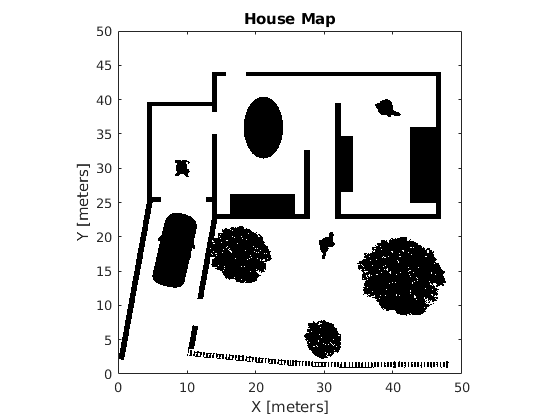

% The purpose of this code is to implement the Jump Point Seach and Safe Flight Corridors and Path Planning Algorithm
% The authors of this code are: Christian Chang, Christopher Poole, Trevor Rizzo and Diana
% Lee Guzman

close all
clear all
clc

%% Process Overview


%% Environment Setup

% MATLAB Toolboxes Needed:
% 
% Parallel Computing Toolbox
% Automated Driving Toolbox
% Symbolic Math Toolbox
% Mapping Toolbox

% ensure figures folder exists
if not(isfolder('figures'))
    mkdir('figures')
end

UAVsize = 0.2;

%% Map Generation

[city_occgrid, city_occgrid_unscaled] = loadMap('city_map.png', 50);
figure
show(city_occgrid_unscaled)
title('City Map')
saveas(gcf,[pwd '/figures/city_map.png'])

inflated_city_occgrid = inflateMap(city_occgrid, UAVsize, 1.0);

[house_occgrid, house_occgrid_unscaled] = loadMap('house_map.png', 50);
figure
show(house_occgrid_unscaled)
title('House Map')
saveas(gcf,[pwd '/figures/house_map.png'])

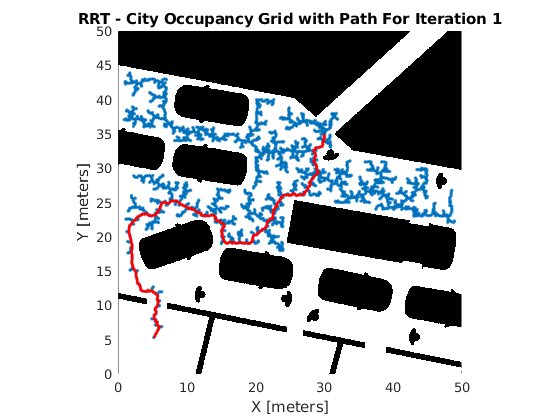

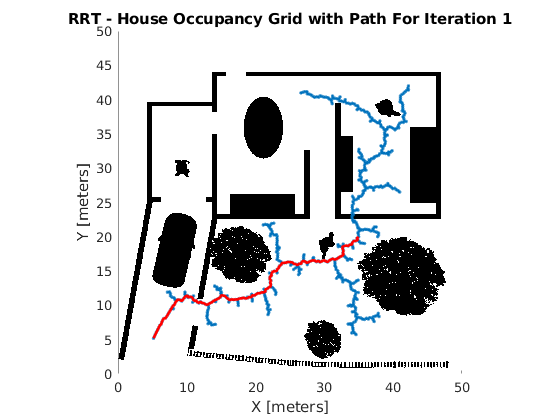

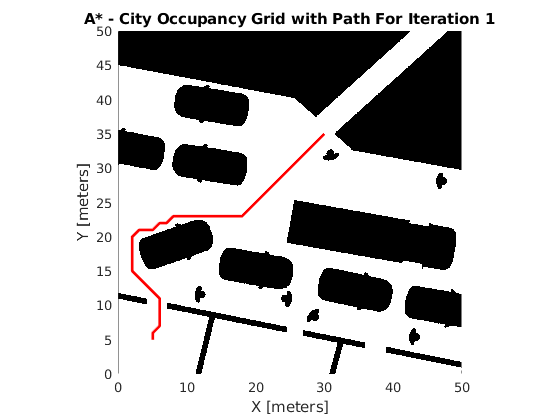

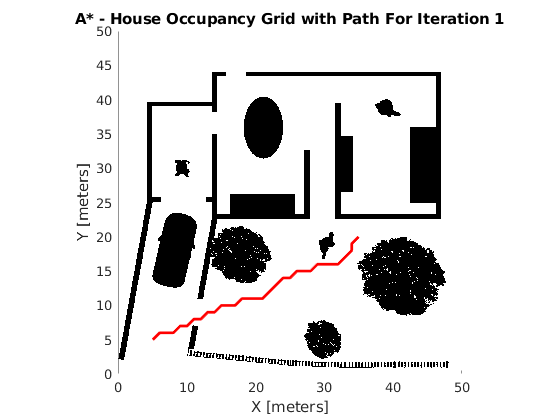

elapsed =          0         0         0         0         0    0.2755


elapsed =          0         0         0         0         0    3.7443


elapsed =          0         0         0         0         0    4.7593


elapsed =          0         0         0         0         0    5.7817


elapsed =          0         0         0         0         0    6.4997


elapsed =          0         0         0         0         0    7.2603


elapsed =          0         0         0         0         0    7.6620


elapsed =          0         0         0         0         0    8.0129


elapsed =          0         0         0         0         0    8.4407


elapsed =          0         0         0         0         0    8.8190


elapsed =          0         0         0         0         0    9.2018


elapsed =          0         0         0         0         0    9.4727


elapsed =          0         0         0         0         0    9.7120


elapsed =          0         0         0         0         0    9.9375


elapsed =          0         0         0         0         0   10.2279


elapsed =          0         0         0         0         0   10.5203


elapsed =          0         0         0         0         0   10.8768


elapsed =          0         0         0         0         0   11.1331


elapsed =          0         0         0         0         0   11.7102


elapsed =          0         0         0         0         0   12.1918


elapsed =          0         0         0         0         0   12.7865


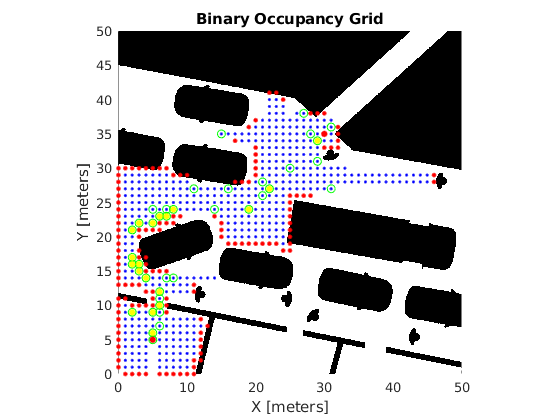

elapsed =          0         0         0         0         0   13.2559


elapsed =          0         0         0         0         0   13.8080


endpoints =    22.4591   26.1892   36.6012   40.3313


endpoints =    22.4591   26.1892   36.6012   40.3313
   22.1662   24.4821   36.6619   38.9778


endpoints =    22.4591   26.1892   36.6012   40.3313
   22.1662   24.4821   36.6619   38.9778
   22.4340   31.8209   36.5761   45.9631


endpoints =    22.4591   26.1892   36.6012   40.3313
   22.1662   24.4821   36.6619   38.9778
   22.4340   31.8209   36.5761   45.9631
   22.3984   24.7143   36.5406   38.8565


endpoints =    22.4591   26.1892   36.6012   40.3313
   22.1662   24.4821   36.6619   38.9778
   22.4340   31.8209   36.5761   45.9631
   22.3984   24.7143   36.5406   38.8565
   22.3378   23.2395   36.8335   37.7351


endpoints =    22.4591   26.1892   36.6012   40.3313
   22.1662   24.4821   36.6619   38.9778
   22.4340   31.8209   36.5761   45.9631
   22.3984   24.7143   36.5406   38.8565
   22.3378   23.2395   36.8335   37.7351
   22.2771   21.7646   36.7728   36.2603


endpoints =    22.4591   26.1892   36.6012   40.3313
   22.1662   24.4821   36.6619   38.9778
   22.4340   31.8209   36.5761   45.9631
   22.3984   24.7143   36.5406   38.8565
   22.3378   23.2395   36.8335   37.7351
   22.2771   21.7646   36.7728   36.2603
   22.2165   20.2897   36.7122   34.7854


Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -Inf is NaN.)
Check function or try again with a different starting value.


Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -Inf is NaN.)
Check function or try again with a different starting value.


Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -Inf is NaN.)
Check function or try again with a different starting value.


intersection_list =    23.8980   27.6281
   35.1020   38.8321
   25.1679   28.8980
   36.3719   40.1020
   28.3636   30.6795
   23.8980   26.2138
   35.1020   37.4179
   26.5821   28.8980
   37.7862   40.1020
   23.8980   33.2849


elapsed =          0         0         0         0    1.0000  -37.9144


elapsed =          0         0         0         0    1.0000  -37.7775


elapsed =          0         0         0         0    1.0000  -37.7513


elapsed =          0         0         0         0    1.0000  -37.7231


elapsed =          0         0         0         0    1.0000  -37.7116


elapsed =          0         0         0         0    1.0000  -37.6753


elapsed =          0         0         0         0    1.0000  -37.6691


elapsed =          0         0         0         0    1.0000  -37.6654


elapsed =          0         0         0         0    1.0000  -37.6611


elapsed =          0         0         0         0    1.0000  -37.6580


elapsed =          0         0         0         0    1.0000  -37.6554


elapsed =          0         0         0         0    1.0000  -37.6498


elapsed =          0         0         0         0    1.0000  -37.6444


elapsed =          0         0         0         0    1.0000  -37.6406


elapsed =          0         0         0         0    1.0000  -37.6365


elapsed =          0         0         0         0    1.0000  -37.6333


elapsed =          0         0         0         0    1.0000  -37.6302


elapsed =          0         0         0         0    1.0000  -37.6273


elapsed =          0         0         0         0    1.0000  -37.6247


elapsed = 1×6
         0         0         0         0    1.0000  -37.6222


elapsed = 1×6
         0         0         0         0    1.0000  -37.6195


elapsed = 1×6
         0         0         0         0    1.0000  -37.6170


elapsed = 1×6
         0         0         0         0    1.0000  -37.6148


elapsed = 1×6
         0         0         0         0    1.0000  -37.6123


elapsed = 1×6
         0         0         0         0    1.0000  -37.6091


elapsed = 1×6
         0         0         0         0    1.0000  -37.6031


elapsed = 1×6
         0         0         0         0    1.0000  -37.5980


elapsed = 1×6
         0         0         0         0    1.0000  -37.5934


elapsed = 1×6
         0         0         0         0    1.0000  -37.3696


elapsed = 1×6
         0         0         0         0    1.0000  -37.3502


elapsed = 1×6
         0         0         0         0    1.0000  -37.3400


elapsed = 1×6
         0         0         0         0    1.0000  -37.3285


elapsed = 1×6
         0         0         0         0    1.0000  -37.3129


elapsed = 1×6
         0         0         0         0    1.0000  -37.3036


elapsed = 1×6
         0         0         0         0    1.0000  -37.2964


elapsed = 1×6
         0         0         0         0    1.0000  -37.2904


elapsed = 1×6
         0         0         0         0    1.0000  -37.2804


elapsed = 1×6
         0         0         0         0    1.0000  -37.2720


elapsed = 1×6
         0         0         0         0    1.0000  -37.2665


elapsed = 1×6
         0         0         0         0    1.0000  -37.2626


elapsed = 1×6
         0         0         0         0    1.0000  -37.2585


elapsed = 1×6
         0         0         0         0    1.0000  -37.2557


elapsed = 1×6
         0         0         0         0    1.0000  -37.2525


elapsed = 1×6
         0         0         0         0    1.0000  -37.2472


elapsed = 1×6
         0         0         0         0    1.0000  -37.2442


elapsed = 1×6
         0         0         0         0    1.0000  -37.2420


elapsed = 1×6
         0         0         0         0    1.0000  -37.2394


elapsed = 1×6
         0         0         0         0    1.0000  -37.2361


elapsed = 1×6
         0         0         0         0    1.0000  -37.2307


elapsed = 1×6
         0         0         0         0    1.0000  -37.2246


elapsed = 1×6
         0         0         0         0    1.0000  -37.2203


elapsed = 1×6
         0         0         0         0    1.0000  -37.2157


elapsed = 1×6
         0         0         0         0    1.0000  -37.1759


elapsed = 1×6
         0         0         0         0    1.0000  -37.1661


elapsed = 1×6
         0         0         0         0    1.0000  -37.1527


elapsed = 1×6
         0         0         0         0    1.0000  -37.1436


elapsed = 1×6
         0         0         0         0    1.0000  -37.1370


elapsed = 1×6
         0         0         0         0    1.0000  -37.1336


elapsed = 1×6
         0         0         0         0    1.0000  -37.1311


elapsed = 1×6
         0         0         0         0    1.0000  -37.1279


elapsed = 1×6
         0         0         0         0    1.0000  -37.1254


elapsed = 1×6
         0         0         0         0    1.0000  -37.1225


elapsed = 1×6
         0         0         0         0    1.0000  -37.1176


elapsed = 1×6
         0         0         0         0    1.0000  -37.1102


elapsed = 1×6
         0         0         0         0    1.0000  -37.1043


elapsed = 1×6
         0         0         0         0    1.0000  -37.0999


elapsed = 1×6
         0         0         0         0    1.0000  -37.0958


elapsed = 1×6
         0         0         0         0    1.0000  -37.0918


elapsed = 1×6
         0         0         0         0    1.0000  -37.0867


elapsed = 1×6
         0         0         0         0    1.0000  -37.0813


elapsed = 1×6
         0         0         0         0    1.0000  -37.0760


elapsed = 1×6
         0         0         0         0    1.0000  -37.0717


elapsed = 1×6
         0         0         0         0    1.0000  -37.0688


elapsed = 1×6
         0         0         0         0    1.0000  -37.0670


elapsed = 1×6
         0         0         0         0    1.0000  -37.0648


elapsed = 1×6
         0         0         0         0    1.0000  -37.0631


elapsed = 1×6
         0         0         0         0    1.0000  -37.0602


elapsed = 1×6
         0         0         0         0    1.0000  -37.0550


elapsed = 1×6
         0         0         0         0    1.0000  -37.0485


elapsed = 1×6
         0         0         0         0    1.0000  -37.0415


elapsed = 1×6
         0         0         0         0    1.0000  -37.0366


elapsed = 1×6
         0         0         0         0    1.0000  -37.0005


elapsed = 1×6
         0         0         0         0    1.0000  -36.9922


elapsed = 1×6
         0         0         0         0    1.0000  -36.9762


elapsed = 1×6
         0         0         0         0    1.0000  -36.9650


elapsed = 1×6
         0         0         0         0    1.0000  -36.9572


elapsed = 1×6
         0         0         0         0    1.0000  -36.9544


elapsed = 1×6
         0         0         0         0    1.0000  -36.9509


elapsed = 1×6
         0         0         0         0    1.0000  -36.9481


elapsed = 1×6
         0         0         0         0    1.0000  -36.9462


elapsed = 1×6
         0         0         0         0    1.0000  -36.9442


elapsed = 1×6
         0         0         0         0    1.0000  -36.9396


elapsed = 1×6
         0         0         0         0    1.0000  -36.9344


elapsed = 1×6
         0         0         0         0    1.0000  -36.9302


elapsed = 1×6
         0         0         0         0    1.0000  -36.9265


elapsed = 1×6
         0         0         0         0    1.0000  -36.9234


elapsed = 1×6
         0         0         0         0    1.0000  -36.9206


elapsed = 1×6
         0         0         0         0    1.0000  -36.8969


elapsed = 1×6
         0         0         0         0    1.0000  -36.8779


endpoints = 1×4
   15.4212   21.2443   35.9232   34.6835


endpoints = 2×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745


endpoints = 3×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745
   15.2824    8.2871   35.7508   39.4375


endpoints = 4×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745
   15.2824    8.2871   35.7508   39.4375
   15.4315    7.3415   35.7386   37.9460


endpoints = 5×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745
   15.2824    8.2871   35.7508   39.4375
   15.4315    7.3415   35.7386   37.9460
   15.2408   29.3741   35.8358   34.9420


endpoints = 6×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745
   15.2824    8.2871   35.7508   39.4375
   15.4315    7.3415   35.7386   37.9460
   15.2408   29.3741   35.8358   34.9420
   15.3880   14.8755   35.5406   35.0280


endpoints = 7×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745
   15.2824    8.2871   35.7508   39.4375
   15.4315    7.3415   35.7386   37.9460
   15.2408   29.3741   35.8358   34.9420
   15.3880   14.8755   35.5406   35.0280
   15.3274   14.8148   35.8335   35.3209


endpoints = 8×4
   15.4212   21.2443   35.9232   34.6835
   15.3117   17.4517   35.8513   32.9745
   15.2824    8.2871   35.7508   39.4375
   15.4315    7.3415   35.7386   37.9460
   15.2408   29.3741   35.8358   34.9420
   15.3880   14.8755   35.5406   35.0280
   15.3274   14.8148   35.8335   35.3209
   15.3482   27.5636   35.5007   47.7161


Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -Inf is NaN.)
Check function or try again with a different starting value.


intersection_list = 62×2
   52.4294   45.5034
   30.1330   30.8880
   31.7653   31.9580
   36.6559   35.1638
   33.8123   33.2998
   33.8123   33.2998
   -3.1344    9.0809
   16.8980   22.2123
   34.1020   33.4897
   16.4184   21.8980


elapsed = 1×6
         0         0         0         0    1.0000  -26.4458


elapsed = 1×6
         0         0         0         0    1.0000  -26.4346


elapsed = 1×6
         0         0         0         0    1.0000  -26.4269


elapsed = 1×6
         0         0         0         0    1.0000  -26.4219


elapsed = 1×6
         0         0         0         0    1.0000  -26.4178


elapsed = 1×6
         0         0         0         0    1.0000  -26.4144


elapsed = 1×6
         0         0         0         0    1.0000  -26.4106


elapsed = 1×6
         0         0         0         0    1.0000  -26.4051


elapsed = 1×6
         0         0         0         0    1.0000  -26.3972


elapsed = 1×6
         0         0         0         0    1.0000  -26.3894


elapsed = 1×6
         0         0         0         0    1.0000  -26.3816


elapsed = 1×6
         0         0         0         0    1.0000  -26.0676


elapsed = 1×6
         0         0         0         0    1.0000  -26.0641


endpoints = 1×4
   12.1295   25.7129   28.5177   31.2450


endpoints = 2×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009


endpoints = 3×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009
   12.3888   25.7130   29.0028   31.7264


endpoints = 4×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009
   12.3888   25.7130   29.0028   31.7264
   12.2165   11.7039   28.8335   28.3209


endpoints = 5×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009
   12.3888   25.7130   29.0028   31.7264
   12.2165   11.7039   28.8335   28.3209
   12.3482   24.5636   28.6117   40.8270


endpoints = 6×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009
   12.3888   25.7130   29.0028   31.7264
   12.2165   11.7039   28.8335   28.3209
   12.3482   24.5636   28.6117   40.8270
   12.3482   18.9067   28.6117   35.1702


endpoints = 7×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009
   12.3888   25.7130   29.0028   31.7264
   12.2165   11.7039   28.8335   28.3209
   12.3482   24.5636   28.6117   40.8270
   12.3482   18.9067   28.6117   35.1702
   12.1558   10.2290   28.7728   26.8461


endpoints = 8×4
   12.1295   25.7129   28.5177   31.2450
   12.4149   25.3192   28.7535   30.9009
   12.3888   25.7130   29.0028   31.7264
   12.2165   11.7039   28.8335   28.3209
   12.3482   24.5636   28.6117   40.8270
   12.3482   18.9067   28.6117   35.1702
   12.1558   10.2290   28.7728   26.8461
   12.4089   21.7958   28.6723   38.0593


Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -Inf is NaN.)
Check function or try again with a different starting value.


intersection_list = 54×2
  133.1318   66.5592
   15.9748   27.0110
   33.4086   32.8960
   14.1947   26.4101
   22.7342   29.2927
   35.5435   33.6167
   18.4645   27.8514
   13.8980   26.3099
   27.1020   30.7672
   -8.0591   18.8980


elapsed = 1×6
         0         0         0         0    1.0000  -22.8193


elapsed = 1×6
         0         0         0         0    1.0000  -22.8147


elapsed = 1×6
         0         0         0         0    1.0000  -22.8123


elapsed = 1×6
         0         0         0         0    1.0000  -22.7931


elapsed = 1×6
         0         0         0         0    1.0000  -22.7917


endpoints = 1×4
    3.2041   22.1020   23.7041   22.1020


endpoints = 2×4
    3.2041   22.1020   23.7041   22.1020
    3.2041   27.1020   23.7041   27.1020


endpoints = 3×4
    3.2041   22.1020   23.7041   22.1020
    3.2041   27.1020   23.7041   27.1020
    3.2041   24.1020   23.7041   24.1020


Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -Inf is NaN.)
Check function or try again with a different starting value.


intersection_list = 10×2
    2.8980   22.1020
   24.1020   22.1020
    2.8980   27.1020
   24.1020   27.1020
    2.8980   24.1020
   24.1020   24.1020
    2.8980         0
    2.8980         0
   24.1020         0
   24.1020         0


elapsed = 1×6
         0         0         0         0    1.0000  -17.8468


elapsed = 1×6
         0         0         0         0    1.0000  -17.8460


elapsed = 1×6
         0         0         0         0    1.0000  -17.8456


elapsed = 1×6
         0         0         0         0    1.0000  -17.8454


elapsed = 1×6
         0         0         0         0    1.0000  -17.8452


elapsed = 1×6
         0         0         0         0    1.0000  -17.8448


elapsed = 1×6
         0         0         0         0    1.0000  -17.8446


elapsed = 1×6
         0         0         0         0    1.0000  -17.8327


elapsed = 1×6
         0         0         0         0    1.0000  -17.8304


endpoints = 1×4
    0.2679   18.8647   14.8823   26.1706


endpoints = 2×4
    0.2679   18.8647   14.8823   26.1706
    0.4591   13.7750   14.6012   27.9171



inflated_house_occgrid = inflateMap(house_occgrid, UAVsize, 1.0);

%% Path Planning

timeout = 10; %timeout is in minutes

start_city = [30,35; 30,36; 31,35];
goal_city = [5,5; 5,6; 6,5];

start_house = [35,20; 35,21; 36,20];
goal_house = [5,5; 5,6; 6,5];

iterations = [1;2;3];
[numRows, numCols] = size(iterations);

%Time Elapsed astar
time_elapsed_astar_grid1 = zeros(numRows,1);
time_elapsed_astar_grid2 = zeros(numRows,1);

%Time Elapsed sfc
time_elapsed_sfc_grid1 = zeros(numRows,1);
time_elapsed_sfc_grid2 = zeros(numRows,1);

%Time elapsed RRT
time_elapsed_rrt_grid1 = zeros(numRows,1);
time_elapsed_rrt_grid2 = zeros(numRows,1);

%Path Distance astar
path_distance_astar_grid1 = zeros(numRows,1);
path_distance_astar_grid2 = zeros(numRows,1);

%Path Distance SFC
path_distance_sfc_grid1 = zeros(numRows,1);
path_distance_sfc_grid2 = zeros(numRows,1);

%Path Distance RRT
path_distance_rrt_grid1 = zeros(numRows,1);
path_distance_rrt_grid2 = zeros(numRows,1);

%Nodes Visited astar
nodes_visited_astar_grid1 = zeros(numRows,1);
nodes_visited_astar_grid2 = zeros(numRows,1);

%Nodes Visited SFC
nodes_visited_sfc_grid1 = zeros(numRows,1);
nodes_visited_sfc_grid2 = zeros(numRows,1);

%Nodes Visited RRT
nodes_visited_rrt_grid1 = zeros(numRows,1);
nodes_visited_rrt_grid2 = zeros(numRows,1);

%Robustness astar
robustness_astar_grid1 = zeros(numRows,1);
robustness_astar_grid2 = zeros(numRows,1);

%Roboustness SFC
robustness_sfc_grid1 = zeros(numRows,1);
robustness_sfc_grid2 = zeros(numRows,1);

%Roboustness RRT
robustness_rrt_grid1 = zeros(numRows,1);
robustness_rrt_grid2 = zeros(numRows,1);

for i = 1:numRows
    
    %RRT
    tic;
    [time_elapsed_rrt, pthObj, solnInfo] = rrt(inflated_city_occgrid, [start_city(i,1) start_city(i,2) 0], [goal_city(i,1) goal_city(i,2) 0]);   
    elapsed = toc;
    mapName = ['RRT - City Occupancy Grid with Path For Iteration ', num2str(i)];
    mapPath = ['/figures/rrt_city_path_', num2str(i),'.png'];
    time_elapsed_rrt_grid1(i,1) = elapsed;
    path_distance_rrt_grid1(i,1) = pathLength(pthObj.States(:,1:2));
    [treeRows, treeCols] = size(solnInfo.TreeData);
    nodes_visited_rrt_grid1(i,1) = treeRows;
    robustness_rrt_grid1(i,1) = solnInfo.IsPathFound;
    plotSolvedPath(city_occgrid_unscaled,solnInfo,pthObj,mapName, mapPath);
    
    clear solnInfo
    clear pthObj
    clear mapName
    clear mapPath
    clear time_elapsed_rrt
    clear treeRows
    clear elapsed
    
    tic;
    [time_elapsed_rrt, pthObj, solnInfo] = rrt(inflated_house_occgrid, [start_house(i,1) start_house(i,2) 0], [goal_house(i,1) goal_house(i,2) 90]);   
    elapsed = toc;
    mapName = ['RRT - House Occupancy Grid with Path For Iteration ', num2str(i)];
    mapPath = ['/figures/rrt_house_path_', num2str(i), '.png'];
    time_elapsed_rrt_grid2(i,1) = elapsed;
    path_distance_rrt_grid2(i,1) = pathLength(pthObj.States(:,1:2));
    [treeRows, treeCols] = size(solnInfo.TreeData);
    nodes_visited_rrt_grid2(i,1) = treeRows;
    robustness_rrt_grid2(i,1) = solnInfo.IsPathFound;
    plotSolvedPath(house_occgrid_unscaled,solnInfo,pthObj,mapName, mapPath);
    
        
    clear solnInfo
    clear pthObj
    clear mapName
    clear mapPath
    clear time_elapsed_rrt
    clear treeRows
    clear elapsed
    
    %A*
    tic;
    [time_elapsed_astar, pthObj, solnInfo] = astar(inflated_city_occgrid,  [start_city(i,1) start_city(i,2) 0], [goal_city(i,1) goal_city(i,2) 0]);
    elapsed = toc;
    mapName = ['A* - City Occupancy Grid with Path For Iteration ', num2str(i)];
    mapPath = ['/figures/a_star_city_path_',num2str(i), '.png'];
    time_elapsed_astar_grid1(i,1) = time_elapsed_astar(6);
    [treeRows, treeCols] = size(pthObj);
    path_distance_astar_grid1(i,1) = pathLength(pthObj);
    nodes_visited_astar_grid1(i,1) = solnInfo.NumNodesExplored;
        if(treeRows > 0)
        robustness_astar_grid1(i,1) = 1;
    else 
        robustness_astar_grid1(i,1) = 1;
    end
    plotSolvedPath(city_occgrid_unscaled,solnInfo,pthObj,mapName, mapPath);
    
        
    clear solnInfo
    clear pthObj
    clear mapName
    clear mapPath
    clear time_elapsed_astar
    clear treeRows
    clear elapsed

    tic;
    [time_elapsed_astar, pthObj, solnInfo] = astar(inflated_house_occgrid,  [start_house(i,1) start_house(i,2) 0], [goal_house(i,1) goal_house(i,2) 90]);
    elapsed = toc;
    time_elapsed_astar_grid2(i,1) = elapsed;
    [treeRows, treeCols] = size(pthObj);
    path_distance_astar_grid2(i,1) = pathLength(pthObj);
    nodes_visited_astar_grid2(i,1) = solnInfo.NumNodesExplored;
    if(treeRows > 0)
        robustness_astar_grid2(i,1) = 1;
    else 
        robustness_astar_grid2(i,1) = 1;
    end
    mapName = ['A* - House Occupancy Grid with Path For Iteration ', num2str(i)];
    mapPath = ['/figures/a_star_house_path_', num2str(i), '.png'];
    plotSolvedPath(house_occgrid_unscaled,solnInfo,pthObj, mapName, mapPath);
    
    clear solnInfo
    clear pthObj
    clear mapName
    clear mapPath
    clear time_elapsed_astar
    clear treeRows
    clear elapsed
    
    % JPS & SFC
    figure
    hold on
    show(city_occgrid_unscaled)
    tic;
    [elapsed_time, nodes_visited, grid, min_path, min_path_len] = sfc(inflated_city_occgrid,  [start_city(i,1) start_city(i,2)], [goal_city(i,1) goal_city(i,2)], timeout);
    elapsed = toc;
    time_elapsed_sfc_grid1(i,1) = elapsed;
    path_distance_sfc_grid1(i,1) = min_path_len;
    nodes_visited_sfc_grid1(i,1) = nodes_visited;
    mapName = ['SFC - City Occupancy Grid with Path For Iteration ', num2str(i)];
    mapPath = ['/figures/sfc_city_path_',num2str(i), '.png'];
    if(~isempty(min_path))
        robustness_sfc_grid1(i,1) = 1;
        plotSolvedPath(city_occgrid_unscaled,[], min_path, mapName, mapPath);
    else
        robustness_sfc_grid1(i,1) = 0;
    end
    
    clear grid
    clear min_path
    clear mapName
    clear mapPath
    clear elapsed_time
    clear min_path_len
    clear elapsed
    
    figure
    hold on
    show(house_occgrid_unscaled)
    tic;
    [elapsed_time, nodes_visited, grid, min_path, min_path_len] = sfc(inflated_house_occgrid, [start_house(i,1) start_house(i,2)] , [goal_house(i,1) goal_house(i,2)], timeout);
    elapsed = toc;
    time_elapsed_sfc_grid2(i,1) = elapsed;
    path_distance_sfc_grid2(i,1) = min_path_len;
    nodes_visited_sfc_grid2(i,1) = nodes_visited;
    mapName = ['SFC - House Occupancy Grid with Path For Iteration ', num2str(i)];
    mapPath = ['/figures/sfc_house_path_', num2str(i), '.png'];
    if(~isempty(min_path))
        robustness_sfc_grid2(i,1) = 1;
        plotSolvedPath(house_occgrid_unscaled,[], min_path, mapName, mapPath);
    else
        robustness_sfc_grid2(i,1) = 0; 
    end
    clear grid
    clear min_path
    clear mapName
    clear mapPath
    clear elapsed_time
    clear min_path_len
    clear elapsed
end



%% Path Analysis


%% Planner Analysis

%Variables for pass/fail ratio
[pass_rrt, fail_rrt, pass_sfc, fail_sfc, pass_astar, fail_astar] = deal(0, 0, 0, 0, 0, 0);

for i = 1:numRows
    %RRT
    if robustness_rrt_grid1(i,1) == 1
        pass_rrt = pass_rrt + 1;
    else
        fail_rrt = fail_rrt +1;
    end
    if robustness_rrt_grid2(i,1) == 1
        pass_rrt = pass_rrt + 1;
    else
        fail_rrt = fail_rrt +1;
    end
    
    %SFC
    if robustness_sfc_grid1(i,1) == 1
        pass_sfc = pass_sfc + 1;
    else
        fail_sfc = fail_sfc +1;
    end
    if robustness_sfc_grid2(i,1) == 1
        pass_sfc = pass_sfc + 1;
    else
        fail_sfc = fail_sfc +1;
    end
    
    %A*
    if robustness_astar_grid1(i,1) == 1
        pass_astar = pass_astar + 1;
    else
        fail_astar = fail_astar +1;
    end
    if robustness_astar_grid2(i,1) == 1
        pass_astar = pass_astar + 1;
    else
        fail_astar = fail_astar +1;
    end
end

%Grab rows & columns
[r1,c1] = size(robustness_sfc_grid1);
[r2,c2] = size(robustness_sfc_grid2);
[r3,c3] = size(robustness_rrt_grid1);
[r4,c4] = size(robustness_rrt_grid2);
[r5,c5] = size(robustness_astar_grid1);
[r6,c6] = size(robustness_astar_grid2);

%Pass/Fail Ratios
sfc_pass = pass_sfc / (c1 + c2);
sfc_fail = fail_sfc / (c1 + c2);
rrt_pass = pass_rrt / (c3 + c4);
rrt_fail = fail_rrt / (c3 + c4);
astar_pass = pass_astar / (c5 + c6);
astar_fail = fail_astar / (c5 + c6);

%Table
T = table(time_elapsed_sfc_grid1, time_elapsed_rrt_grid1, time_elapsed_astar_grid1, path_distance_sfc_grid1, path_distance_rrt_grid1, path_distance_astar_grid1, nodes_visited_sfc_grid1, nodes_visited_rrt_grid1, nodes_visited_astar_grid1, robustness_sfc_grid1, robustness_rrt_grid1, robustness_astar_grid1)
T = table(time_elapsed_sfc_grid2, time_elapsed_rrt_grid2, time_elapsed_astar_grid2, path_distance_sfc_grid2, path_distance_rrt_grid2, path_distance_astar_grid2, nodes_visited_sfc_grid2, nodes_visited_rrt_grid2, nodes_visited_astar_grid2, robustness_sfc_grid2, robustness_rrt_grid2, robustness_astar_grid2)

%Figure 1: Elapsed Time City Map
figure
scatter(iterations,time_elapsed_sfc_grid1, "black", "filled")
hold on;
grid on;
scatter(iterations,time_elapsed_rrt_grid1, "red", "filled")
scatter(iterations,time_elapsed_astar_grid1, "blue", "filled")
xlabel('Iterations');
ylabel('Time (s)');
ylim([0 inf])
title ("Elapsed Time City Map");
legend('sfc', 'rrt', 'astar');

hold off;

%Figure 2: Elapsed Time House Map
figure
scatter(iterations,time_elapsed_sfc_grid2, "blue", "filled")
hold on;
grid on;
scatter(iterations,time_elapsed_rrt_grid2, "cyan", "filled")
scatter(iterations,time_elapsed_astar_grid2, "red", "filled")
xlabel('Iterations') 
ylabel('Time (s)') 
ylim([0 inf]);
title ("Elapsed Time House Map")
legend('sfc', 'rrt', 'astar');

hold off;

%Figure 3: Path Distance City Map
figure
scatter(iterations,path_distance_sfc_grid1, "black", "filled")
hold on;
grid on;
scatter(iterations,path_distance_rrt_grid1, "red", "filled")
scatter(iterations,path_distance_astar_grid1, "blue", "filled")
xlabel('Iterations') 
ylabel('Distance (m)') 
ylim([0 inf]);
title ("Path Distance City Map")
legend('sfc', 'rrt', 'astar');

hold off;

%Figure 4: Path Distance House Map
figure
scatter(iterations,path_distance_sfc_grid2, "blue", "filled")
hold on;
grid on;
scatter(iterations,path_distance_rrt_grid2, "cyan", "filled")
scatter(iterations,path_distance_astar_grid2, "red", "filled")
xlabel('Iterations') 
ylabel('Distance (m)') 
ylim([0 inf]);
title ("Path Distance House Map")
legend('sfc', 'rrt', 'astar');

hold off;

%Figure 5: Nodes Visited City Map
figure
scatter(iterations,nodes_visited_sfc_grid1, "black", "filled")
hold on;
grid on;
scatter(iterations,nodes_visited_rrt_grid1, "red", "filled")
scatter(iterations,nodes_visited_astar_grid1, "blue", "filled")
xlabel('Iterations') 
ylabel('Nodes Visited (nodes)') 
ylim([0 inf]);
title ("Nodes Visited City Map")
legend('sfc', 'rrt', 'astar');

hold off;

%Figure 6: Nodes Visited House Map
figure
scatter(iterations,nodes_visited_sfc_grid2, "blue", "filled")
hold on;
grid on;
scatter(iterations,nodes_visited_rrt_grid2, "cyan", "filled")
scatter(iterations,nodes_visited_astar_grid2, "red", "filled")
xlabel('Iterations');
ylabel('Nodes Visited (nodes)'); 
ylim([0 inf]);
title ("Nodes Visited House Map");
legend('sfc', 'rrt', 'astar');

hold off;

%Figure 7: Robustness SFC on both maps
figure
labels = {'Pass','Fail'};
pie([sfc_pass, sfc_fail]);
title ("SFC Robustness");
legend(labels)

%Figure 8: Robustness RRT on both maps
figure
labels = {'Pass','Fail'};
pie([rrt_pass, rrt_fail]);
title ("RRT Robustness");
legend(labels)

%Figure 9: Robustness A* on both maps
figure
labels = {'Pass','Fail'};
pie([astar_pass, astar_fail])
title ("A* Robustness")
legend(labels)

